table = readtable("../cpp/output/coordinateOutput.csv")

table = 9312303×6 table
    simulationID    particleID    depth       x         y           z     
    ____________    __________    _____    _______    ______    __________

         6              0           0            0         0             0
         6              0           0            0         0         28415
         6              0           0      -2.8363    4.9649         31518
         6              0           0      -12.485    47.174         63373
         6              0           0       -17.49    66.211         69796
         6              0           0      -18.022    68.922         72195
         6              0           0       -24.31    78.577         75222
         6              0           0      -68.624    112.77         84404
         6           

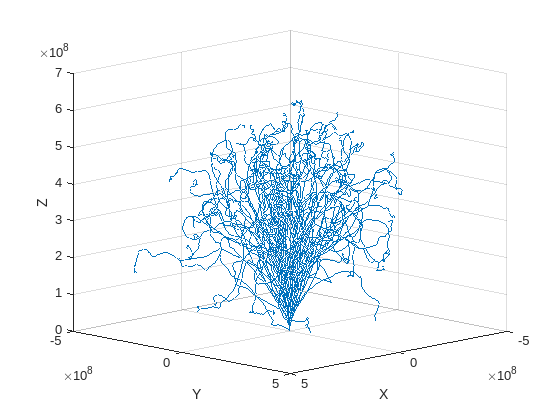

clf; 

filter = false;
    
% Define marker size
marker_size = 2; % Adjust as needed

if filter
    target =  0;
    filtered1 = table(table.depth == target, :)
    idx = size(filtered1, 1)
    % idx = 471742
    x = filtered1.x(1:idx);
    y = filtered1.y(1:idx);
    z = filtered1.z(1:idx);
else
    x = table.x;
    y = table.y;
    z = table.z;
end

scatter3(x, y, z, marker_size, 'filled')
% plot3(x,y,z);
xlabel("X")
ylabel("Y")
zlabel("Z")
view([3,3,1])
% view([0, 0])
grid on;

% xlim([-150,150])
% ylim([-150,150])
% zlim([0, 1000])